# SGN quantification

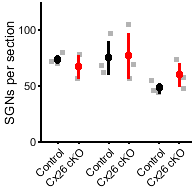

%P7

conSGNapex21 = [70,80,72];
conSGNmid21 = [62,97,68];
conSGNbase21 = [44,46,55];

ckoSGNapex21 = [57,78];
ckoSGNmid21 = [57,69,105];
ckoSGNbase21 = [58,48,74];

conapex = [223.7851662,280.7510089,231.3699026]/10;
conmid = [218.4175298,309.4394998,277.3925104]/10;
conbase = [219.4513716,283.6879433,258.2402103]/10;

ckoapex = [285.1140456,254.8936309]/10;
ckomid = [214.3260011,237.6933411,301.7935158]/10;
ckobase = [333.8513786,240.0360054,283.4380267]/10; 


ylbl = ('SGNs per section');
ylbl2 = ('SGNs per 100 um2');
dim = [2 2];
conditions = {'Control','Cx26 cKO','Control','Cx26 cKO','Control','Cx26 cKO'};
compare6(conSGNapex21,ckoSGNapex21,conSGNmid21,ckoSGNmid21,conSGNbase21,ckoSGNbase21,conditions,ylbl,dim);
ylim([0 125])

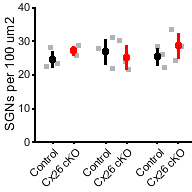


figure
compare6(conDenapex21,ckoDenapex21,conDenmid21,ckoDenmid21,conDenbase21,ckoDenbase21,conditions,ylbl2,dim);
ylim([0 40])

% [h, p] = ttest2(conSGNapex21,ckoSGNapex21)

h = 0

p = 0.5121

% [h, p] = ttest2(conSGNmid21,ckoSGNmid21)

h = 0

p = 0.9446

% [h, p] = ttest2(conSGNbase21,ckoSGNbase21)

h = 0

p = 0.2322

% 
% [h, p] = ttest2(conDenapex21,ckoDenapex21)

h = 0

p = 0.4067

% [h, p] = ttest2(conDenmid21,ckoDenmid21)

h = 0

p = 0.6699

% [h, p] = ttest2(conDenbase21,ckoDenbase21)

h = 0

p = 0.3863


% better stats
geno = {'con','con','con','con','con','con','con','con','con','cko','cko','cko','cko','cko','cko','cko','cko',}';
mouse = [1 1 1 2 2 2 3 3 3 4 4 4 5 5 5 6 6 ]';
location = {'apex','middle','base','apex','middle','base','apex','middle','base','apex','middle','base','apex','middle','base','middle','base'}'; 
SGNs = [conapex(1),conmid(1),conbase(1),conapex(2),conmid(2),conbase(2),conapex(3),conmid(3),conbase(3),ckoapex(1),ckomid(1),ckobase(1),ckoapex(2),ckomid(2),ckobase(2),ckomid(3),ckobase(3)]';


tbl = table(geno,mouse,location,SGNs,'VariableNames',{'Genotype','Mouse','Location','SGNs'})

lme = fitlme(tbl,'SGNs~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')
[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

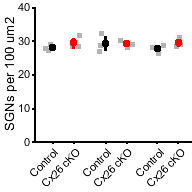

%P21

% conSGNapex21 = [70,80,72];
% conSGNmid21 = [62,97,68];
% conSGNbase21 = [44,46,55];
% 
% ckoSGNapex21 = [57,78];
% ckoSGNmid21 = [57,69,105];
% ckoSGNbase21 = [58,48,74];

conDenapex21 = [27.62946645,28.89143943,27.2003049];
conDenmid21 = [28.719035,32.22838459,26.94892691];
conDenbase21 = [26.36359015,27.97577558,28.46668194];

ckoDenapex21 = [28.15372843,28.32366428,31.58576751];
ckoDenmid21 = [30.22146426,28.95891201,28.01650702];
ckoDenbase21 = [28.85052626,28.34488053,30.89550933]; 

apex = [conDenapex21,ckoDenapex21];
mid = [conDenmid21,ckoDenmid21];
base = [conDenbase21,ckoDenbase21];
ylbl = ('SGNs per section');
ylbl2 = ('SGNs per 100 um2');
dim = [2 2];
conditions = {'Control','Cx26 cKO','Control','Cx26 cKO','Control','Cx26 cKO'};
% compare6(conSGNapex21,ckoSGNapex21,conSGNmid21,ckoSGNmid21,conSGNbase21,ckoSGNbase21,conditions,ylbl,dim);
% ylim([0 125])

figure
compare6(conDenapex21,ckoDenapex21,conDenmid21,ckoDenmid21,conDenbase21,ckoDenbase21,conditions,ylbl2,dim);
ylim([0 40])

% [h, p] = ttest2(conSGNapex21,ckoSGNapex21)
% [h, p] = ttest2(conSGNmid21,ckoSGNmid21)
% [h, p] = ttest2(conSGNbase21,ckoSGNbase21)
% 
% [h, p] = ttest2(conDenapex21,ckoDenapex21)
% [h, p] = ttest2(conDenmid21,ckoDenmid21)
% [h, p] = ttest2(conDenbase21,ckoDenbase21)

% rm anova model
geno2 = {'con','con','con','cko','cko','cko'}';
tbl2 = table(geno2,apex',mid',base','VariableNames',{'genos','f1','f2','f3'})

tbl2 = 6×4 table
     genos       f1        f2        f3  
    _______    ______    ______    ______

    {'con'}    27.629    28.719    26.364
    {'con'}    28.891    32.228    27.976
    {'con'}      27.2    26.949    28.467
    {'cko'}    28.154    30.221    28.851
    {'cko'}    28.324    28.959    28.345
    {'cko'}    31.586    28.017    30.896


freqs = table([1 2 3]','VariableNames',{'location'});
rm = fitrm(tbl2,'f1-f3~genos','WithinDesign',freqs)

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [6×4 table]
         ResponseNames: {'f1'  'f2'  'f3'}
    BetweenFactorNames: {'genos'}
          BetweenModel: '1 + genos'

   Within Subjects:
          WithinDesign: [3×1 table]
     WithinFactorNames: {'location'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [2×3 table]
            Covariance: [3×3 table]


ranovatbl = ranova(rm)

ranovatbl = 3×8 table
                            SumSq     DF    MeanSq        F       pValue     pValueGG    pValueHF    pValueLB
                            ______    __    _______    _______    _______    ________    ________    ________

    (Intercept):location    1.6303    2     0.81513    0.34904     0.7156    0.63072     0.67349     0.58643 
    genos:location           3.451    2      1.7255    0.73884    0.50763    0.46238     0.48517      0.4385 
    Error(location)         18.683    8      2.3354                                                          
